clear all
close all
clc

%Peter corke
a1 = 12;
a2 = 14;
a3 = 6;
a4 = 4;

q1 = 0;%Theta1
q2 = 0;%Theta2

R(1) = Link('revolute','d',a1,'alpha',pi/2,'a',a2,'offset',0);
R(2) = Link('revolute','d',a3,'alpha',0,'a',a4,'offset',0);

Robot = SerialLink(R,'name','Bender')

 
Robot = 
 
Bender (2 axis, RR, stdDH, fastRNE)                              
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         12|         14|      1.571|          0|
|  2|         q2|          6|          4|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


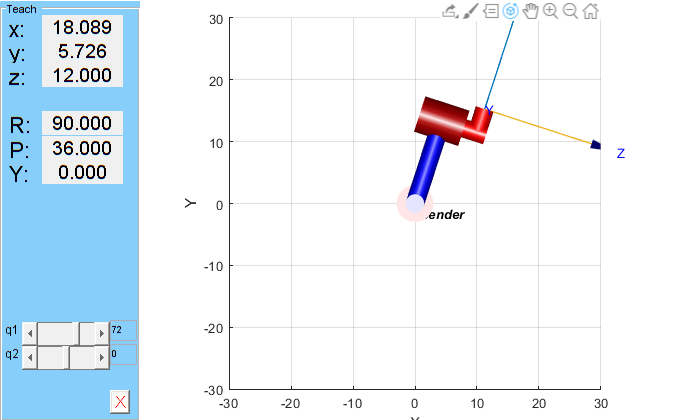


Robot.plot([q1,q2],'scale',1.0,'workspace',[-30 30 -30 30 -30 30]);
zlim([-15,30]);
Robot.teach([q1,q2],'rpy/zyx');

MTH = Robot.fkine([q1,q2])

MTH =     1.0000         0         0   18.0000
         0    0.0000   -1.0000   -6.0000
         0    1.0000    0.0000   12.0000
         0         0         0    1.0000



%Matriz (DH)
TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 a1; 0 0 0 1]

TZ0 =      1     0     0     0
     0     1     0     0
     0     0     1    12
     0     0     0     1


RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]

RZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX1 = [1 0 0 a2; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX1 =      1     0     0    14
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX1 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(pi/2) 0; 0 0 0 1]

RX1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T01 =  TZ0*RZ0*TX1*RX1

T01 =     1.0000         0         0   14.0000
         0    0.0000   -1.0000         0
         0    1.0000    0.0000   12.0000
         0         0         0    1.0000


T01 =  RZ0*TZ0*RX1*TX1

T01 =     1.0000         0         0   14.0000
         0    0.0000   -1.0000         0
         0    1.0000    0.0000   12.0000
         0         0         0    1.0000



TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 a3; 0 0 0 1]

TZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     6
     0     0     0     1


RZ1 = [cos(q2) -sin(q2) 0 0; sin(q2) cos(q2) 0 0; 0 0 1 0; 0 0 0 1]

RZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX2 = [1 0 0 a4; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX2 =      1     0     0     4
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX2 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T12 =  TZ1*RZ1*TX2*RX2

T12 =      1     0     0     4
     0     1     0     0
     0     0     1     6
     0     0     0     1


T12 =  RZ1*TZ1*RX2*TX2

T12 =      1     0     0     4
     0     1     0     0
     0     0     1     6
     0     0     0     1



T02 = T01*T12

T02 =     1.0000         0         0   18.0000
         0    0.0000   -1.0000   -6.0000
         0    1.0000    0.0000   12.0000
         0         0         0    1.0000



%Confirmar la rotación en ángulos de Euler
m = T02(1:3,1:3)

m =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


r = rad2deg(tr2rpy(m,'zyx'))

r =      0     0    90
